# Lab A: Constructing Basic Graph Matrices 1

## Part 1 Prelab Review: Degree Matrix and Adjacency Matrix

### **Example: **

*Please examine the simple graph below and make sure you know what each symbol (number in the circle, the label *$e_i$*, and the arrow) represents, and how the **degree matrix* $D$ *and **adjacency matrix*$\Delta$ *are constructed -- you should know this if you completed the prelab!*

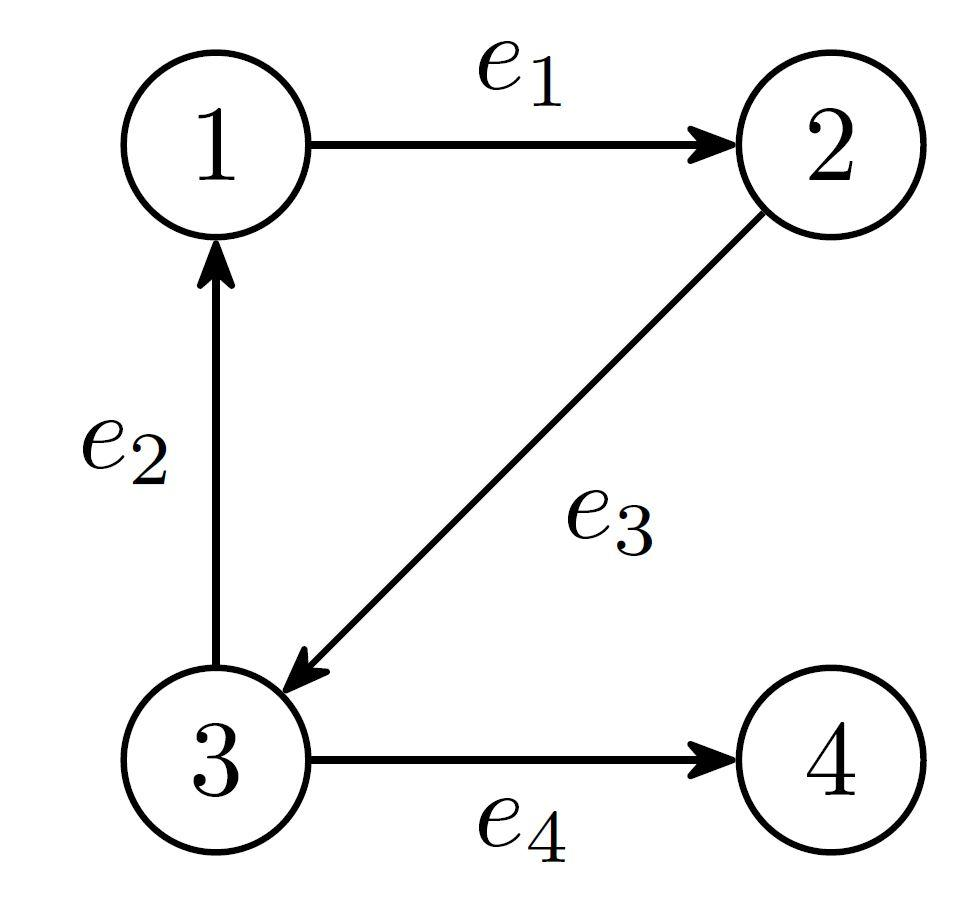


$$D = \pmatrix{
2 & 0 & 0 & 0 \cr
0 & 2 & 0 & 0 \cr
0 & 0 & 3 & 0 \cr
0 & 0 & 0 & 1
}, \quad 
\Delta = \pmatrix{
0 & 1 & 1 & 0 \cr
1 & 0 & 1 & 0 \cr
1 & 1 & 0 & 1 \cr
0 & 0 & 1 & 0
}.$$


### **Exercise: Construct the Degree Matrix **$D$** and the Adjacency Matrix **$\Delta$ (Delta) for the following graphs and display the results:

#### Question 1.1

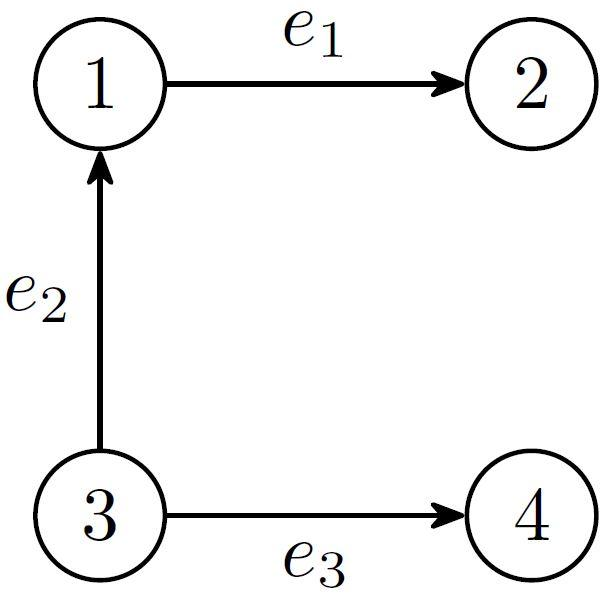 

% your code here
D1 = diag([2 1 2 1])

D1 =      2     0     0     0
     0     1     0     0
     0     0     2     0
     0     0     0     1


Delta1 = [0 1 1 0; 1 0 0 0; 1 0 0 1; 0 0 1 0]

Delta1 =      0     1     1     0
     1     0     0     0
     1     0     0     1
     0     0     1     0


#### Question 1.2

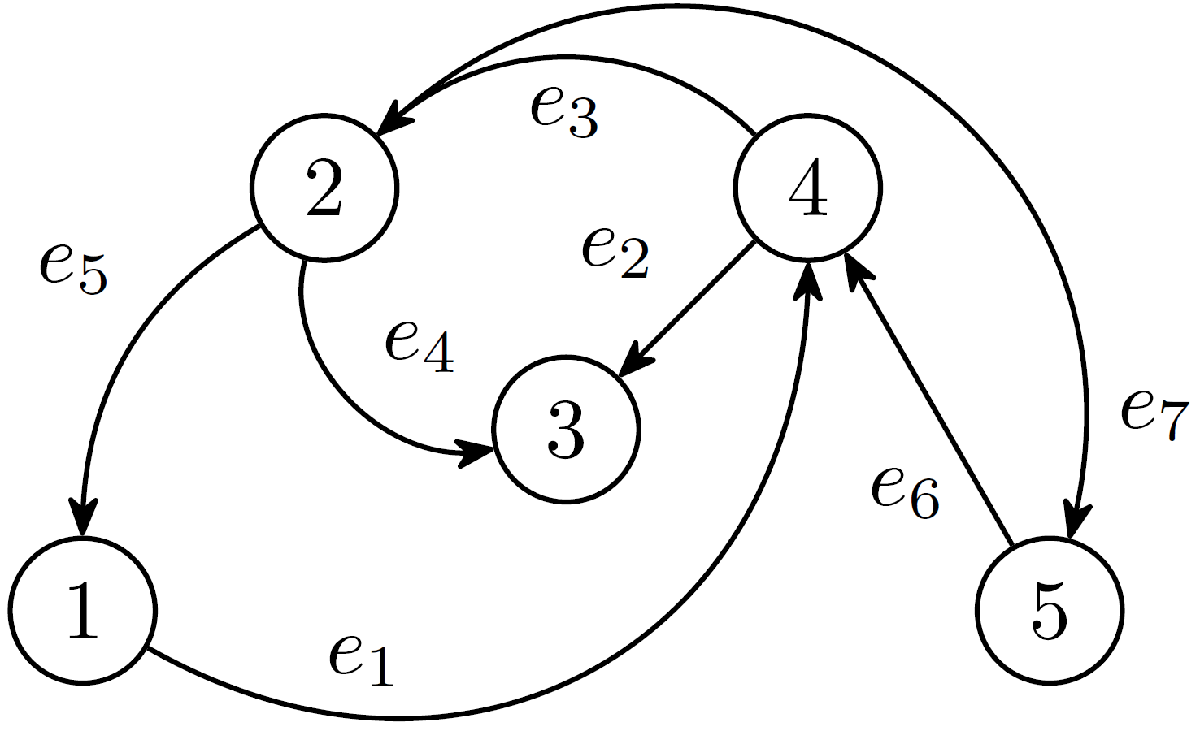

% your code here
D2 = diag([2 4 2 4 2])

D2 =      2     0     0     0     0
     0     4     0     0     0
     0     0     2     0     0
     0     0     0     4     0
     0     0     0     0     2


Delta2 = [0 1 0 1 0; 1 0 1 1 1; 0 1 0 1 0; 1 1 1 0 1; 0 1 0 1 0]

Delta2 =      0     1     0     1     0
     1     0     1     1     1
     0     1     0     1     0
     1     1     1     0     1
     0     1     0     1     0


## Part 2 **Construction of the Node-Edge Incidence Matrix **

We now introduce another important graph matrices: the ***node-edge incidence matrix ***$A$. Unlike the degree and adjacency matrix, $A$ is not a square matrix in general. However, it characterize more than just the nodal relationships, and has an interesting connection to both $D$ and $\Delta$.

First, we discuss how the node-edge incidence matrix $A$ is constructed element-wise: structurally, 

- the **columns** of $A$ represent the **edges** in the graph $G$, and

- the **rows** of $A$ represent the **nodes** in the graph $G$,

The $i, k$-th entry of $A$, $A_{ik}$ is $1$ if edge $e_k$ **leaves** node $i$,  $-1$ if $e_k$ **enters** node $i$, and $0$ otherwise. (Think: how many $1$ and $-1$'s should there be in each column of $A$? Again, the $k$-th column of $A$ represents the edge $e_k$.) 

If we use $n$ to denote the number of nodes in the graph $G$ and $m$ to denote the number of edges, then $A$ is an $n \times m$ matrix. 

### Example:

For the graph below, 

First, convince yourself that since there are four nodes,$\{1,2,3,4\}$ and three edges $\{e_1, e_2, e_3\}$, the $A$ matrix should be $4 \times 3$. We can construct the $A$ matrix as $A = 
\pmatrix{
1 & -1  & 0 \cr 
-1 & 0 & 1 \cr
0 & 1 & -1 \cr
0 & 0 & 0 
} $. Convince yourself that this makes sense: consider the first **column** $\pmatrix{1 \cr -1 \cr 0 \cr 0}$, which represents the **edge** $e_1$: it leaves node $1$ and enters node $2$, so there should be $1$ in the first entry (corresponds to node $1$) and $-1$ in the second entry (corresponds to node $2$). Consider the second **column** $\pmatrix{-1 \cr 0 \cr 1 \cr 0}$, which represents the edge $e_2$: it leaves node $3
$ and enters node $1$, so there should be $1$ in the third entry (corresponds to node $3$) and $-1$ in the first entry (corresponds to node $1$). 

Try to argue similarly about the third column of $A$ and if you can interpret them with respect to the edge $e_3$.

Now, we are ready to do some exercises!

### Exercise: Construct the Node-Edge Incidence Matrix and display the results

#### Question 2.1

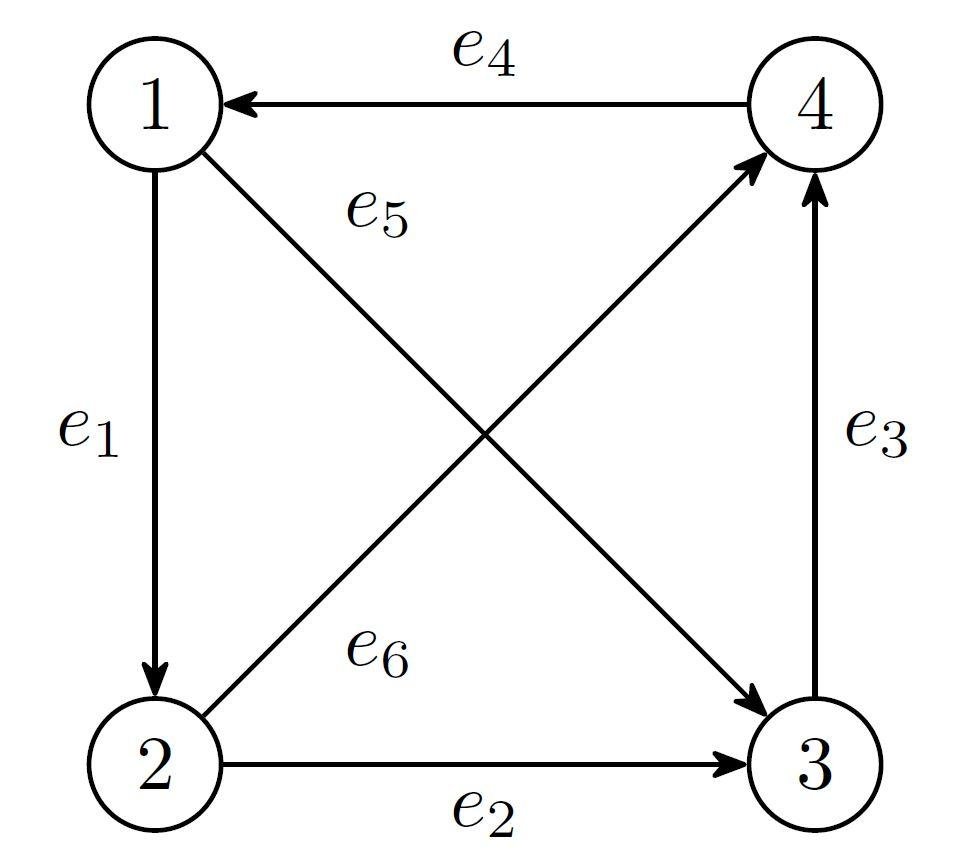

% your code here
A1 = [[1;-1;0;0] [0;1;-1;0] [0;0;1;-1] [-1;0;0;1] [1;0;-1;0] [0;1;0;-1]]

A1 =      1     0     0    -1     1     0
    -1     1     0     0     0     1
     0    -1     1     0    -1     0
     0     0    -1     1     0    -1


#### Question 2.2

% your code here
A2 = [[1;0;0;-1;0] [0;0;-1;1;0] [0;-1;0;1;0] [0;1;-1;0;0] [-1;1;0;0;0] [0;0;0;-1;1] [0;1;0;0;-1]]

A2 =      1     0     0     0    -1     0     0
     0     0    -1     1     1     0     1
     0    -1     0    -1     0     0     0
    -1     1     1     0     0    -1     0
     0     0     0     0     0     1    -1


## Part 3: Simple Properties of Node-Edge Incidence Matrix 

#### **Question 3.1**

You have learned about the rank, nullity, and kernel of a matrix in class. Now, think about the structure of the matrix $A$, take a guess on what the **maximum rank** of $A$ can be in terms of the number of nodes $n$ and edges $m$, and give a one-sentence justification to your answer. (Hint: for our purposes, it always holds that $m \geq n - 1$.)

*————————————————————————————————*

*Your answer: *

**The maximum rank of A is **$n-1$**. Since a matrix with more columns than rows (**$m>n$**) has either no solutions or infinite solutions, the matrix must have at least 1 solution (and so **$\textrm{rank}\left(A\right)\le m$**), and **$m\ge n-1$**; the maximum rank of A is taken when A has the fewest possible number of columns and so the maximum possible rank of A is **$n-1$**.**

*————————————————————————————————*

#### **Question 3.2**

Following your answer above, what is the **minimum nullity** of the matrix $A$? Justify your answer in one sentence. (Hint: use Rank-Nullity Theorem.)

*————————————————————————————————*

*Your answer: *

**By the rank-nullity theorem, **$\dim \left(\textrm{imA}\right)+\dim \left(\textrm{kerA}\right)=\textrm{rank}\left(A\right)+\textrm{nullity}\left(A\right)=m$**; since the maximum rank of A is **$n-1$**, the minimum nullity of A must be **$m-\textrm{rank}\left(A\right)=m-\left(n-1\right)=m-n+1$**.**

*————————————————————————————————*

#### **Question 3.3**

For the graph below, is the vector $v = \pmatrix{1 \cr 1 \cr 0 \cr -1 \cr 1 \cr 0 \cr 0}$ in the null space of $A$? How about the vector $u = \pmatrix{0 \cr -1 \cr 0 \cr 1 \cr 0 \cr -1 \cr -1}$? Construct the vectors `u,v` and test it. 

% Your code here

% Define u and v
u = [1;1;0;-1;1;0;0]

u =      1
     1
     0
    -1
     1
     0
     0


v = [0;-1;0;1;0;-1;-1]

v =      0
    -1
     0
     1
     0
    -1
    -1



% Then, test whether u, v are in the kernel of A2, which you constructed previously
A2*u

ans =      0
     0
     0
     0
     0


A2*v

ans =      0
     0
     0
     0
     0


Your next lab will introduce another interesting graph matrix called **Edge-Cycle Incidence Matrix**, and will be an extension to this question. 

#### **Question 3.4**

We can compute the basis of the kernel of any matrix $M$ by finding all linearly independent, nonzero vectors $x$ such that $M x = 0$. Matlab can conveniently find all such $x$ for us with the command `null`:

Take the matrix $M = \pmatrix{1 & 0 & -1 \cr -1 & 1 & 0 \cr 0 & -1 & 1}$, we can check that the kernel of $A$ is spanned by a single vector by running the following command:

M = [1 0 -1; -1 1 0; 0 -1 1];
null(M)

ans =     0.5774
    0.5774
    0.5774


The `null` command on its own generates an *orthonormal basis *for $\mathrm{ker}(A)$, which you will learn about soon (or have learned recently). We can get a "nicer" kernel basis by additionally using the option `'r'` in the command like so 

null(M, 'r')

ans =      1
     1
     1


This option generates a *rational basis *of $\mathrm{ker}(A)$, if the matrix $M$ is relatively small and contains integer elements. However, if the matrix is large and contain non-integer elements, it can be extremely slow and possibly fail. 

**Exercise**: Find the rational kernel basis for the node-edge incidence matrices for **both** graphs in **Question 2.1 and 2.2** and display the results. 

% Your code here
rkb1 = null(A1, 'r')

rkb1 =      1    -1     0
     1    -1    -1
     1     0    -1
     1     0     0
     0     1     0
     0     0     1


rkb2 = null(A2, 'r')

rkb2 =      0     1     0
    -1     0     0
     1     1     1
     1     0     0
     0     1     0
     0     0     1
     0     0     1


**Note**: If the kernel is spanned by more than a single vector, the result will be a matrix, whose columns are the spanning vectors. 

#### **Question 3.5**

Now, refer back to the degree matrix, adjacency matrix from Part 1. For **both** graphs in **Question 2.1 and 2.2**, construct the degree and adjacency matrices $D, \Delta$, and compute 

- 
$$D - \Delta$$


- 
$$AA^{T}$$


Display and compare these results:

% Your code here
% GRAPH 1
D2_1 = diag([3 3 3 3]);
Delta2_1 = [0 1 1 1; 1 0 1 1; 1 1 0 1; 1 1 1 0];
% 1.
D2_1-Delta2_1

ans =      3    -1    -1    -1
    -1     3    -1    -1
    -1    -1     3    -1
    -1    -1    -1     3


% 2.
A1*A1'

ans =      3    -1    -1    -1
    -1     3    -1    -1
    -1    -1     3    -1
    -1    -1    -1     3


% GRAPH 2
D2_2 = diag([2 4 2 4 2]);
Delta2_2 = [0 1 0 1 0; 1 0 1 1 1; 0 1 0 1 0; 1 1 1 0 1; 0 1 0 1 0];
% 1.
D2_2-Delta2_2

ans =      2    -1     0    -1     0
    -1     4    -1    -1    -1
     0    -1     2    -1     0
    -1    -1    -1     4    -1
     0    -1     0    -1     2


A2*A2'

ans =      2    -1     0    -1     0
    -1     4    -1    -1    -1
     0    -1     2    -1     0
    -1    -1    -1     4    -1
     0    -1     0    -1     2



% test that A and A^T are equal
A1*A1'-(A1*A1')'

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


A2*A2'-(A2*A2')'

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


What do you notice about how $D - \Delta$ and $AA^T$ compare? Are they symmetric matrices? Explain in at most two sentences. 

*————————————————————————————————*

*Your observation*: $D - \Delta$** and **$AA^T$** are equal matrices and are each symmetric (i.e. equal to their transpose).**

*————————————————————————————————*